# Visualizing Cricket Statistics

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code loads and plots the data.

stats = readtable("./data/cricketers.csv");
% Show the data
stats

stats = 275×3 table
           Name           BattingAvg    BowlingAvg
    __________________    __________    __________

    {'Bob Willis'    }       11.5          25.2   
    {'Tony Greig'    }      40.43          32.2   
    {'Chris Old'     }      14.82         28.11   
    {'Mike Hendrick' }        6.4         25.83   
    {'Graham Gooch'  }      42.58         46.47   
    {'Phil Edmonds'  }       17.5         34.18   
    {'Geoff Miller'  }       25.8         30.98   
    {'John Lever'    }      11.76         26.72   
    {'Ian Botham'    }      33.54          28.4   
    {'John Emburey'  }      22.53          38.4   
    {'Graham Dilley' }      13.35         29.76   
    {'Derek Pringle' }       15.1         35.97   
    {'Neil Foster'   }      11.73         32.85   
    {'Phil DeFreitas'}      14.82         33.57   
    {'Angus Fraser'  }       7.46         27.32   
    {'Devo

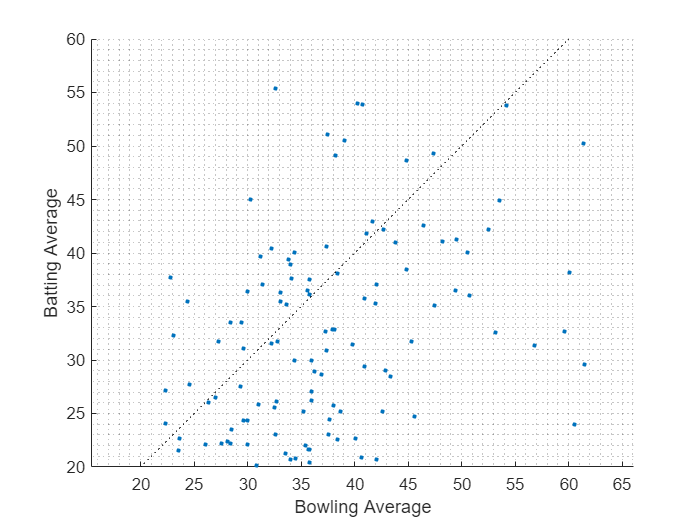

% Extract data into separate variables
x = stats.BowlingAvg;
y = stats.BattingAvg;
name = stats.Name;
% Make a scatter plot of averages
scatter(x, y, 6, "filled")
hold on
plot([20 60], [20 60], "k:")
hold off
xlim([20 60])
xlabel("Bowling Average")
ylim([20 60])
ylabel("Batting Average")
axis equal
grid minor

## Task 1

The table `stats` contains averages for 275 players. The first step is to extract the players that are considered “all-rounders”. A simple criterion for this is any player that has a batting average higher than their bowling average (these players correspond to data points above the dashed line in the scatter plot).

The table `stats` contains three variables: `Name`, `BattingAvg`, and `BowlingAvg`. Recall that you can access individual variables within a table using dot notation: `T.varname`. You can perform logical indexing with these variables in the same way you've done it previously with numeric variables.

higherbat = (stats.BattingAvg > stats.BowlingAvg);

## Task 2

You can use a logical array as an index into an array of any data type.

allround = stats(higherbat, :)

allround = 36×3 table
           Name           BattingAvg    BowlingAvg
    __________________    __________    __________

    {'Tony Greig'    }      40.43          32.2   
    {'Ian Botham'    }      33.54          28.4   
    {'Joe Root'      }      48.68         44.81   
    {'Ben Stokes'    }      37.04         31.38   
    {'Greg Chappell' }      53.86          40.7   
    {'Allan Border'  }      50.56          39.1   
    {'Steve Waugh'   }      51.06         37.44   
    {'Mark Waugh'    }      41.81         41.16   
    {'Simon Katich'  }      45.03         30.23   
    {'Andrew Symonds'}      40.61         37.33   
    {'Michael Clarke'}       49.1         38.19   
    {'Shane Watson'  }      35.19         33.68   
    {'Hansie Cronje' }      36.41         29.95   
    {'Brian McMillan'}      39.36         33.82   
    {'Shaun Pollock' }      32.31         23.11   
    {'Ja

## Task 3

Recall that you can specify the size and color of the markers in a scatter plot.

`scatter``(``x``,``y``,``sz``,``clr``,``"filled"``)`

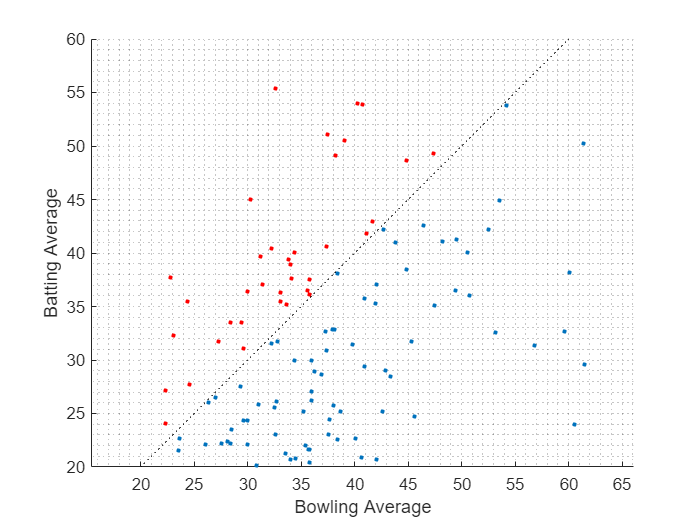

hold on
scatter(allround.BowlingAvg, allround.BattingAvg, 6, "r", "filled")
hold off

## Task 4

To complete the visualization, you will add the names of certain players to the plot, colored according to whether they excel at batting or bowling.

Note that the batting and bowling averages were extracted into the arrays `y` and `x`, respectively.

bat = y > 50;
bowl = x < 25;

## Task 5

You can use the `text` function to add text to a plot:

`text``(``x``,``y``,``txt``)`

where `x` and `y` are numeric arrays and `txt` is an array of text (the same length as `x` and `y`). As with all visualization functions, you can set visual properties such as color with extra input pairs

`text``(``x``,``y``,``txt``,``"Color"``,``c``)`

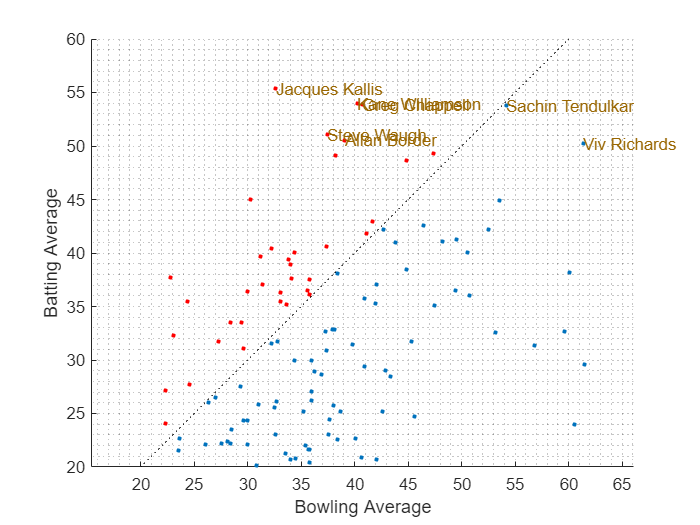

text(x(bat), y(bat), name(bat), "Color", [0.6 0.4 0])

## Task 6

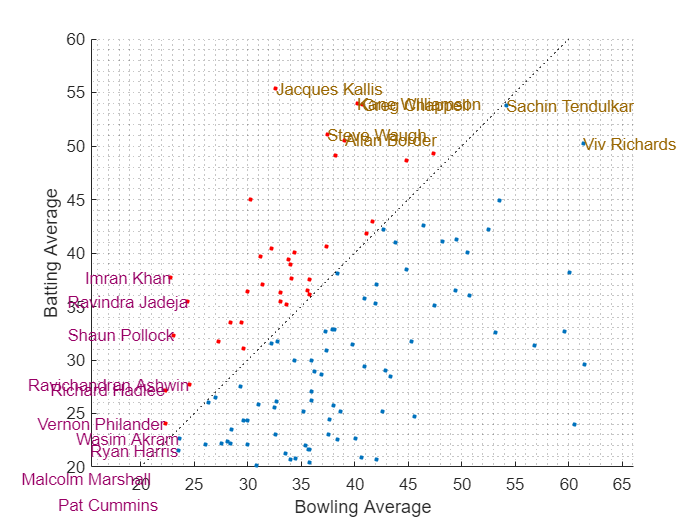

text(x(bowl), y(bowl), name(bowl), "Color", [0.6 0 0.4], "HorizontalAlignment", "right")

## Task 7

Recall that you can combine logical variables with `&` (and), `|` (or), and `~` (not). You can use parentheses to ensure the order of operations is what you intend.

idx = higherbat & ~(bat|bowl);
numAR = nnz(idx)

numAR = 25